# Setting up Langevin integrator with dephasing only

The Langevin equation has both noise and dissipation terms originating from each local bath the system interacts with. 

The dissipation is a deterministic drag, and the noise acts like a stochastic forcing.The strength of dissipation and the variance of the noise are related via fluctuation dissipation relation: $\langle\eta(t)\eta(t\prime)\rangle = 2\gamma T \delta(t-t\prime)$, where the noise is proportional to $\eta(t)$, $\gamma$ is the dissipation strength, and $T$ is the temperature bath.

The **EnvironmentParams **works by specifying the dissipation strength and temperature of each bath. However this framework is problematic if we want to see only the noise effects (ie. the dephasing-only limit). This is the limit of $\gamma\rightarrow 0, \gamma T\rightarrow \text{const.}$ The workflow for using **evolve_langevin()** has workarounds built in for this case, which will be illustrated in this tutorial.

First let's setup the system and Hamiltonian variables. Let's look at solving the unstructured search problem on a hypercube graph formed by the computational basis of N=4 qubits. In this problem we start off in an equal superposition of all the computational basis states and aim to shift some of the probability amplitude of the state onto a `marked' basis state. We'll do this using a quantum walk Hamiltonian, with an energy modification on the marked state ( [https://arxiv.org/abs/1709.00371](https://arxiv.org/abs/1709.00371) ). The relative strengths of these parts must be chosen to maximize the amplitude transfer onto the marked state. This is achieved by the following:

$\hat\mathcal{H} = - q \sum_{n=1}^N \hat\sigma_x^{(n)} - |m\rangle\langle m|$,

where

$q = 2^{-(N+1)}\sum_{n=1}^{N}{N\choose n} \frac{1}{n}$.

N = 4; %no. qubits
spinDimList = 2*ones([1 N]); % list of local Hilbert space dimensions for system
Dmax = maxBondDim(spinDimList); % max bond dimension for full description
totalDim = prod(spinDimList);

X = [0 1;1 0];  % Pauli-X matrix
Z = [1 0;0 -1]; % Pauli-Z matrix
I = eye(2);    % 2x2 identity matrix

q = 0;
for n=1:N, q = q + 2^(-(N+1))*nchoosek(N,n)/n; end

m = randi([1 totalDim]); % choose marked state
fprintf('\nm=%i',m)


m=12

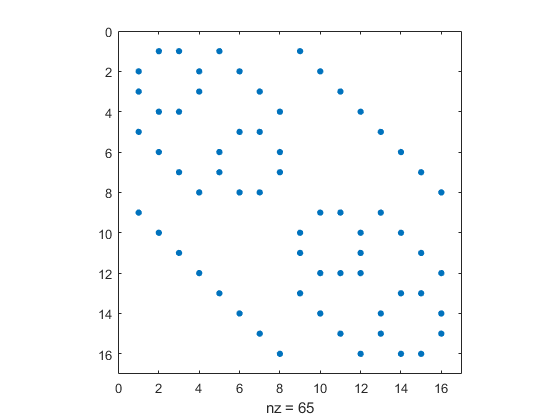

proj_m = zeros(totalDim);
proj_m(m,m) = 1; % proj_m = |m><m|

% Now make H in matrix form:
Hmat = - q*(kronlist({X,I,I,I}) + ... % 'kronlist' performed Kronecker product on
         kronlist({I,X,I,I}) + ... % the cell-array of matrices provided.
         kronlist({I,I,X,I}) + ...
         kronlist({I,I,I,X})) ...
       - proj_m;

spy(Hmat) % plot of sparcity pattern of H


% Finally reshape Hmat into a (spinDimList x spinDimList) tensor
H = permute(reshape(Hmat,[spinDimList spinDimList]),[N:-1:1, 2*N:-1:N+1]);

Now let's setup the initial state: a coherent superposition of all the computational basis states (as defined by the Pauli-Z matrix). This can be found by acting on `0^N> with \sum_n (X_n + Z_n)/2, which rotates each |0> to a (|0>+|`1>)/2

mpsInit = generate_productstate_mps(spinDimList,Dmax);
% n=1
mpsInit{2}{1} = .5*(X+Z)*mpsInit{2}{1};

% n=2:N-1
for n=2:N-1
    mpsInit{n+1}{1} = ncon({.5*(X+Z),mpsInit{n+1}{1}},{[-3 1],[-1 -2 1]});
end

% n=N
mpsInit{N+1}{1} = mpsInit{N+1}{1}*.5*(X+Z).';

Finally let's set up the environment. We will look at the dephasing limit where each qubit is coupled locally the environment via the x-direction.

EnvParams = EnvironmentParams(N); % initialize environment object
for n=1:N
    % now add the couplings
    gamma = 0; % no dissipation
    T = 1; % temperature
    F = X; % coupling operator
    EnvParams.add_Fn(n,F,gamma,T)
end

Now we have set everything up we're ready to run. Getting evolve_langevin to only calculate the noise terms is quite simple, and is controlled by the 'noise_only' keyword argument of **evolve_langevin()**, which should be set to 'true', like this:

**evolve_langevin( ..., 'noise_only', true, ....).**

First let's look at how we do with no environment:

[mps_series,time_series] = evolve_langevin(mpsInit,H,20.,200);

% % uncomment for a general look at the results
% plot_mps_series(mps_series,time_series)

Let's calculate and plot the probability of measuring m with a computational basis measurement. We'll do this in a scalable way by measuring the qubits one-by-one with projectors. Eg. if m=2 and N=4, then binary(m) = 0010 (where Z|0> =| `0> and Z|1>=-0|1>), so we do`


$$|m\rangle\langle m|\psi\rangle = \hat{P}_0\hat{P}_0\hat{P}_1\hat{P}_0 |\psi\rangle$$


and find the inner product of this with itself which equals $|\langle m|\psi\rangle|^2$.

P0 = [1 0;0 0];
P1 = [0 0;0 1];
binary_m = dec2bin(m-1,N); % binary starts at zero, matlab starts at 1

proj_list = cell([1 N]); % create list of projectors onto m
for n=1:N
    nth_digit = binary_m(n);
    switch nth_digit
        case '0'
            proj_list{n} = P0;
        case '1'
            proj_list{n} = P1;
    end
end

nSamples = length(time_series);
marked_state_fidelity_series = zeros([1 nSamples]);
for iSample = 1:nSamples
    mps = mps_series{iSample};
    
    % Project onto |m>:
    % n=1
    mps{2}{1} = proj_list{1}*mps{2}{1};
    % n=2:N-1
    for n=2:N-1
        mps{n+1}{1} = ncon({proj_list{n},mps{n+1}{1}},{[-3 1],[-1 -2 1]});
    end
    % n=N
    mps{N+1}{1} = mps{N+1}{1}*proj_list{N}.'; 
    
    % Compute self-fidelity |<mps|mps>| = |<psi(t)|m>|^2
    marked_state_fidelity_series(iSample) = fidelity_mps(mps,mps);
end

Now plot

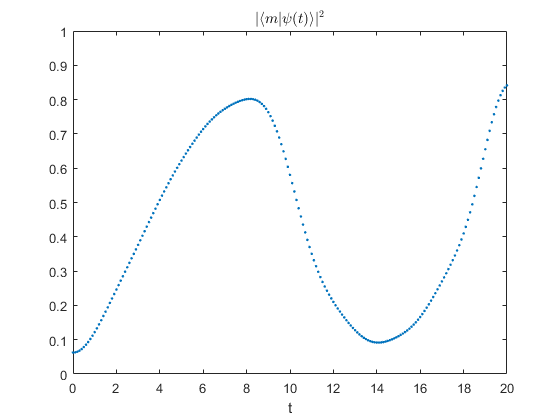

figure
plot(time_series,marked_state_fidelity_series,'.')
xlabel('t')
xlim([0 time_series(end)])
ylim([0 1])
title('$|\langle m|\psi(t)\rangle|^2$','interpreter','Latex')

Good! We have rotated to the marked state with a little better than 80% accuracy, from 6.25% accuracy initially. Now let's add our environment and set **noise_only** to true:

[mps_series,time_series] = evolve_langevin(mpsInit,H,20.,200,'EnvParams',EnvParams,...
                                           'noise_only',true);

Operands to the || and && operators must be convertible to logical scalar values.

Error in evolve_langevin>input_parser (line 303)
                if KWARGS.is_frictionless && ~KWARGS.suppress_frictionless_warning

Error in evolve_langevin (line 27)
    KWARGS = input_p


% Calculate and plot |<m|psi>|^2
marked_state_fidelity_series_2 = zeros([1 nSamples]);
for iSample = 1:nSamples
    mps = mps_series{iSample};
    
    % Project onto |m>:
    % n=1
    mps{2}{1} = proj_list{1}*mps{2}{1};
    % n=2:N-1
    for n=2:N-1
        mps{n+1}{1} = ncon({proj_list{n},mps{n+1}{1}},{[-3 1],[-1 -2 1]});
    end
    % n=N
    mps{N+1}{1} = mps{N+1}{1}*proj_list{N}.'; 
    
    % Compute self-fidelity |<mps|mps>| = |<psi(t)|m>|^2
    marked_state_fidelity_series_2(iSample) = fidelity_mps(mps,mps);
end

figure
plot(time_series,marked_state_fidelity_series_2,'.')
xlabel('t')
xlim([0 time_series(end)])
ylim([0 1])
title('$|\langle m|\psi(t)\rangle|^2$','interpreter','Latex')